Per effettuare un'analisi automatica e classi�care il cancro della cervice uterina, è necessaria una fase di segmentazione che consiste, all'interno della regione esaminata, nella separazione delle cellule dallo sfondo e dei nuclei dal citoplasma. Data l'immagine img.bmp, realizzate una segmentazione in tre classi cercando di avvicinarvi al risultato ideale contenuto nell'immagine img seg ideal.bmp.

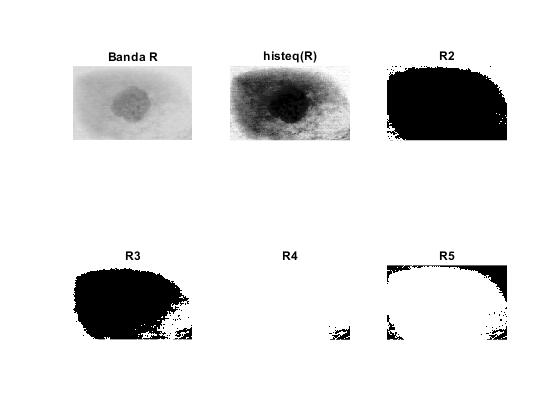

close all; clear all; clc;
x = double(imread('img.bmp'))/255;
xo = double(imread('img_seg_ideal.bmp'));

% RGB to GRAY
R = x(:,:,1);
G = x(:,:,2);
B = x(:,:,3);

[M N] = size(R);

R1 = histeq(R);
R2 = R1>0.9;
R3 = R>0.8;

R4 = R3(150:end,260:end);
[m n] = size(R4);
R4 = padarray(R4,[M-m, N-n],1,'pre');

mask1 = (1-R2).*R4;
mask2 = R<0.6;

% Visualizzazione Maschera
figure; 
subplot(231); imshow(R); title('Banda R');
subplot(232); imshow(R1); title('histeq(R)');
subplot(233); imshow(R2); title('R2');
subplot(234); imshow(R3); title('R3');
subplot(235); imshow(R4); title('R4');
subplot(236); imshow(mask1); title('R5');

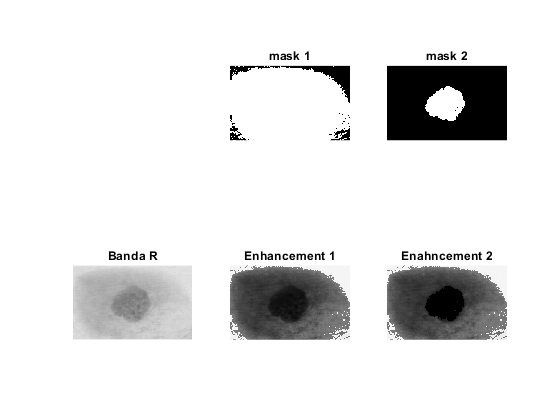


% Enhancement con mask che delimita la cellula
y1 = mask1.*(R.^4)+(1-mask1).*(R.^0.3);
y2 = mask2.*(y1.^10)+(1-mask2).*y1;  

figure; 
subplot(232); imshow(mask1); title('mask 1');
subplot(233); imshow(mask2); title('mask 2');
subplot(234); imshow(R); title('Banda R');
subplot(235); imshow(y1); title('Enhancement 1');
subplot(236); imshow(y2); title('Enahncement 2');

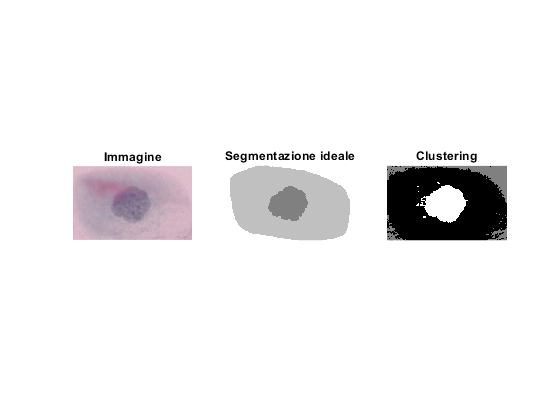


% Clustering
idx = exKmeans(y2(:),3);
y3 = reshape(idx,size(y2));

% Visualizzazione
figure;
subplot(131); imshow(x); title('Immagine');
subplot(132); imshow(xo,[]); title('Segmentazione ideale');
subplot(133); imshow(y3,[]); title('Clustering');